## **Prerequisites**

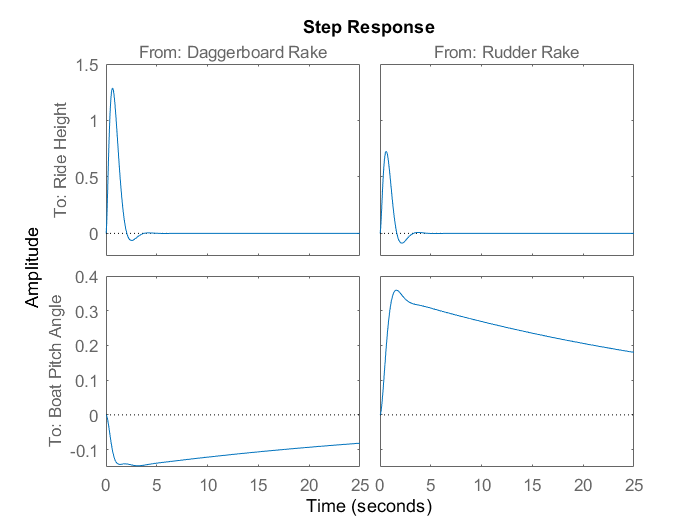

clear 
clc
% Add YALMIP to local path (NOTE:INPUT YOUR OWN LOCAL PATH)
addpath(genpath("C:\Users\amato\OneDrive\Documenten\TU\MSC S&C\Year 1\Q3 23-24\MPC"))

## **Continuous Time State Space **

% Continuous Time State Space of AC45
A = [-0.135 -4.905 0.125 0.176 4.902;
      0.180 -7.132 -1.419 -0.075 -7.132;
      0 -0.768 -1.315 0.014 -0.768;
      0 10.85 0 0 0;
      0 0 1 0 0]; 
B = [-4.078 4.555 -1.254 0 0;
     -0.226 2.566 2.378 0 0]';
C = [0 0 0 1 0;
     0 0 0 0 1];
D = [];

%Choose Sampling Period 
h = 0.5; %in seconds

## **Discretize System using ZOH and sampling period h (without disturbance)**

%Create DT SS
h=0.5; %Inter-sampling time in seconds
Psi=expm(A*h);
fun=@(t)expm(A.*t);
Gamma=integral(fun,0,h,'ArrayValued',1)*B;

%Check Controllability
CO_dt = ctrb(Psi,Gamma); %Controllability Matrix
if rank(CO_dt) == size(Psi,1) && min(svd(CO_dt)) >= 0.01
    fprintf("DT System Controllable :)")
else
    warning("DT System not Controllable :(")
end

DT System Controllable :)


%Check Observability
OBS_dt = obsv(Psi,C); %Obs matrix
if rank(OBS_dt) == size(Psi,1) && min(svd(OBS_dt)) >= 0.01
    fprintf("DT System Observable :)")
else
    warning("DT System not Observable :(")
end

DT System Observable :)

## **Discrete Time State Space**

%Assign Matrices to Struct
AC45.A=Psi; AC45.B=Gamma;
AC45.C=C; AC45.D=D;
AC45.d=[0.03;0.01];

% Definition of system dimensions
dim.nx = size(AC45.A, 1);    % state dimension
dim.ny = size(AC45.C, 1);    % output dimension
dim.nu = size(AC45.B, 2);    % input dimension
dim.N = 20;                  % receding horizon
dim.d = size(AC45.d,1);                   % disturbance dimension

%Augmented SS for observer
AC45.Bd = [1 0;0.5 1;zeros(dim.nx-2,dim.d)]; % disturbance on first state
AC45.Cd = [1 0; 0.5 0]; % Disturbance on ride height & pitch angle
AC45.M=0.005*eye(dim.nx); AC45.N=0.005*eye(dim.ny);

A_tilde = [AC45.A, AC45.Bd; zeros(dim.d,dim.nx), eye(dim.d)];
C_tilde = [AC45.C AC45.Cd];

%Check Observability of augmented system
OBS_aug_dt = [eye(dim.nx)-AC45.A -AC45.Bd; AC45.C AC45.Cd];
if rank(OBS_aug_dt) == dim.nx+dim.d && min(svd(OBS_aug_dt)) >= 0.01
    fprintf("Aug. DT System Observable :)")
else
    warning("Aug. DT System not Observable :(")
end

Aug. DT System Observable :)


%Assign observer poles (eigenvalues of (A-LC))
observer_poles = linspace(0.3,0.4,dim.nx+dim.d); %fast poles
L_tilde = place(A_tilde', C_tilde', observer_poles); %Observer gain

%Extended system matrices
ext_AC45.A = A_tilde;
ext_AC45.B = [Gamma; zeros(1, dim.nu)];
ext_AC45.C = C_tilde;
ext_AC45.D = D;
ext_AC45.L = L_tilde';
ext_AC45.L1 = ext_AC45.L(1:dim.nx,:); ext_AC45.L2 = ext_AC45.L(dim.nx+1:end,:);

% Definition of system dimensions
ext_dim.nx = size(ext_AC45.A, 1);    % extended state dimension
ext_dim.ny = size(ext_AC45.C, 1);    % output dimension
ext_dim.nu = size(ext_AC45.B, 2);    % input dimension
ext_dim.N = dim.N;                   % simulation horizon

## **Prediction Model**

%Prediction matrix from initial state
T = zeros(dim.nx*(dim.N+1),dim.nx);
for k = 0:dim.N
    T(k*dim.nx+1:(k+1)*dim.nx,:) = AC45.A^k;
end

%Prediction matrix from input
S = zeros(dim.nx*(dim.N+1),dim.nu*(dim.N));
for k = 1:dim.N
    for i = 0:k-1
        S(k*dim.nx+1:(k+1)*dim.nx,i*dim.nu+1:(i+1)*dim.nu) = AC45.A^(k-1-i)*AC45.B;
    end
end

%Assign to struct
predmod.T = T;
predmod.S = S;

## **Weights, Cost Function and Observer Gain**

%Definition of quadratic cost function
weight.Q = diag([0.1 10 1 100 1]);   %weight on states
weight.R = diag([1 0.1]);               %weight on input

%Solve DARE
[P,K,eig_DARE] = idare(Psi,Gamma,weight.Q,weight.R); 
K = -K; weight.P=P;

%Generate Cost Function
Qbar = blkdiag(kron(eye(dim.N),weight.Q),weight.P); 
Rbar=kron(eye(dim.N),weight.R); 
H=S'*Qbar*S+Rbar;
mu_x0=S'*Qbar*T;
mu_xref=-S'*Qbar*kron(ones(dim.N+1,1),eye(dim.nx));
mu_uref=-Rbar*kron(ones(dim.N,1),eye(dim.nu));
mu=[mu_x0 mu_xref mu_uref];

## Constraints

%Input Constraints
F1 = [0 1 0 0 -1; 
      0 -1 0 0 1; 
      0 0 0 0 0; 
      0 0 0 0 0];
E1 = [1 0;-1 0;0 1;0 -1];
e1 = [12;12;5;5];

%Tight State Constraints
F2 = [0 0 0 1 0;
      0 0 0 -1 0];
e2 = [0.5; 0.315];

%Loose State Constraints
F3 = [0 0 0 0 1; %theta (pitch angle)
      0 0 0 0 -1;
      1 0 0 0 0; %V_H (Hydrodynamic speed)
      -1 0 0 0 0; 
      0 1 0 0 0; %gamma (flight path angle)
      0 -1 0 0 0;
      0 0 1 0 0; %q (angular velocity)
      0 0 -1 0 0];
e3 = [20; 20; 
      5; 5; %m/s
      20;20; 
      20; 20];

%Compact notation of constraints
F =[F1; F2; F3]; E =[E1; zeros(2,2); zeros(8,2)];
e = [e1;e2;e3];

## Terminal Set

*We employ a hyperrhombus as an outer approximation of the elliptic terminal set. The vertices of the rhombus are constructed using the fact that the eigenvalues of P dictate the position where the eigenvectors intersect the ellipse boundary.*

%(Orthogonally) Diagonalize P
[V_p,D_p] = eig(P); %Check for x'TPx instead of 1/2x'TPx, numerically more reliable
V_p'*V_p %Visually check that V_p is an orthogonal basis, i.e. product is identity

ans =     1.0000   -0.0000   -0.0000    0.0000    0.0000
   -0.0000    1.0000    0.0000   -0.0000    0.0000
   -0.0000    0.0000    1.0000    0.0000    0.0000
    0.0000   -0.0000    0.0000    1.0000   -0.0000
    0.0000    0.0000    0.0000   -0.0000    1.0000



c = 2; %Level curve of your choice, iterate

%Define hyperrhombus vertices approximating ellipsoid
rh_vert = 2*(inv(D_p)*(c*ones(size(D_p,1),1))); %Construct column vector of vertices

%Transform coordinates for both signs
rh_vert_tf = V_p*rh_vert;

%Check constraints, per region
if F*rh_vert_tf + E*(K*rh_vert_tf) <= e
    fprintf('Constraints are satisfied')
else
    warning('Constraints are not satisfied')
end

Constraints are satisfied

## Optimal Control Problem (reference tracking):

%Request simulation time
prompt = "Input simulation time: ";
T_sim = input(prompt)

T_sim = 40


%Number of Experiments
dim.exp = 5;
%Nexp=[10 12 15 20];

% Initialize Results
x=zeros(dim.nx*dim.exp,T_sim+1);x_init=[0, 0, 0, -0.1, 0];
x(:,1)=kron(ones(dim.exp,1),x_init'); %Initial condition
u_rec = zeros(dim.nu*dim.exp,T_sim); %Input Sequence
y=zeros(dim.ny*dim.exp,T_sim+1);%Output Sequence

xhat=zeros(dim.nx,T_sim+1); xhat(:,1)=[0, 0.05, 0, 0, -0.05]; %Initial condition
AC45.y_ref=[0.3;0]; %Output target
yhat=zeros(dim.ny,T_sim+1);%Output
dhat=zeros(dim.d,T_sim+1); dhat(:,1)=zeros(dim.d,1); %Estimated disturbance


%Terminal Set, last lines of S and T (i.e., x(N))
constraints.Ae=predmod.S(end-dim.nx+1:end,:); 
constraints.be=predmod.T(end-dim.nx+1:end,:);

%Concatenate Constraint LMIs
F_diag = kron(eye(dim.N),F); %block diagonal F matrix
E_diag = kron(eye(dim.N),E); %block diagonal E matrix
e_concat = kron(ones(dim.N,1),e);

%Start opt. time cumulative
sol_data.yalmiptime=0; sol_data.solvertime=0;

% Receding horizon implementation
for exp=1:dim.exp
    id_y=2:2:dim.exp*dim.ny;
    id_u=2:2:dim.exp*dim.nu;
    for k = 1:T_sim
        sel_index=linspace(1,dim.nx,dim.nx)+(exp-1)*dim.nx*ones(dim.nx,1);
        x_0_real=x(sel_index(1):sel_index(end),k);
        xhat_0 = xhat(:,k);
        %x_0_real = x(:,k);
        
        %%OPTIMAL TARGET SELECTION
        %Define Optimization Variables
        x_r = sdpvar(dim.nx,1); u_r = sdpvar(dim.nu,1);
        %Define Constraints
        ots.cons_mat=[eye(dim.nx) - AC45.A, -AC45.B; AC45.C, zeros(dim.ny,dim.nu)]; 
        ots.cons_ref=[ots.cons_mat*[x_r;u_r]==[AC45.Bd*dhat(:,k+1);AC45.y_ref-AC45.Cd*dhat(:,k+1)]];
        ots.cons_state=[F*x_r + E*u_r <= e];
        ots.cons_all=[ots.cons_ref; ots.cons_state];
        %Define Objective
        ots.obj = [norm(u_r)];
        %% Solve OTS
        ops =  sdpsettings('verbose',0);                         
        sol_ots = optimize(ots.cons_all,ots.obj, ops);              
        % Analyze error flags (break if wrong)
        if sol_ots.problem ~ 0
            warning('Something went wrong!');
            sol_ots.info
            yalmiperror(sol_ots.problem)
            warning('Loop Terminated!');
            break
        end
        %Extract values of minimizer: reference input and -state
        u_r=value(u_r); x_r=value(x_r);
        
        %% OPTIMAL CONTROL PROBLEM (with YALMIP)
        u_con = sdpvar(dim.nu*dim.N,1);                          %define optimization variable
        x_N = constraints.Ae*u_con + constraints.be*xhat_0;         %Terminal State
        %Constraints: terminal set and general constraints
        constraints.terminal = [(x_N-x_r)'*P*(x_N-x_r) <= c];    
        constraints.state = [F_diag*T(dim.nx+1:end,:)*xhat_0 + (F_diag*S(dim.nx+1:end,:)+E_diag)*u_con <= e_concat];
        constraints.all = [constraints.terminal;constraints.state];
        %Objective Function
        Objective = 0.5*u_con'*H*u_con+(mu*[xhat_0; x_r; u_r])'*u_con;%define objective function
        %Optimize
        ops =  sdpsettings('verbose',0,'cachesolvers',1,'saveduals',0);                        
        sol = optimize(constraints.all,Objective, ops);          %solve the problem
        % Analyze error flags
        if sol.problem ~ 0
            warning('Something went wrong!');
            sol.info
            yalmiperror(sol.problem)
            warning('Loop Terminated!');
            break
        end
        %Save YALMIP and Solvertime
        sol_data.yalmiptime = sol_data.yalmiptime + sol.yalmiptime;
        sol_data.solvertime = sol_data.solvertime + sol.solvertime;
        %Extract solution
        u_con=value(u_con);                                       
        % Select the first input only
        %u_rec(1:2,k)=u_con(1:2);
        u_rec(id_u(exp)-1:id_u(exp),k)=u_con(1:2);
        clear u_con x_r u_r
        
        %Compute the actual state/output evolution
        u=u_rec(id_u(exp)-1:id_u(exp),k);
        x(sel_index(1):sel_index(end),k+1)=AC45.A*x_0_real + AC45.B*u + AC45.Bd*AC45.d + AC45.M*randn(dim.nx,1);
        y(id_y(exp)-1:id_y(exp),k)=AC45.C*x(sel_index(1):sel_index(end),k) + AC45.Cd*AC45.d+ AC45.N*randn(dim.ny,1); %Actual Measured Output
        % Compute the estimated state/output evolution
        meas_update = y(id_y(exp)-1:id_y(exp),k)-C_tilde*[xhat(:,k);dhat(:,k)]; 
        xhat(:,k+1)=AC45.A*xhat_0 + AC45.B*u + AC45.Bd*dhat(:,k) + ext_AC45.L1*meas_update;
        yhat(:,k)=AC45.C*xhat(:,k) + AC45.Cd*dhat(:,k); %Estimated Output
        
        %Compute disturbance estimation
        dhat(:,k+1)=dhat(:,k)+ext_AC45.L2*meas_update; 
    end
end

ans = logical
   1


ans = 'Infeasible problem (<a href="yalmip.github.io/debugginginfeasible">learn to debug</a>) (CONEPROG)'

ans = 'Infeasible problem (<a href="yalmip.github.io/debugginginfeasible">learn to debug</a>) '

ans = logical
   1


ans = 'Infeasible problem (<a href="yalmip.github.io/debugginginfeasible">learn to debug</a>) (CONEPROG)'

ans = 'Infeasible problem (<a href="yalmip.github.io/debugginginfeasible">learn to debug</a>) '

ans = logical
   1


ans = 'Infeasible problem (<a href="yalmip.github.io/debugginginfeasible">learn to debug</a>) (CONEPROG)'

ans = 'Infeasible problem (<a href="yalmip.github.io/debugginginfeasible">learn to debug</a>) '

ans = logical
   1


ans = 'Infeasible problem (<a href="yalmip.github.io/debugginginfeasible">learn to debug</a>) (CONEPROG)'

ans = 'Infeasible problem (<a href="yalmip.github.io/debugginginfeasible">learn to debug</a>) '


disp('Average Yalmip and Solver time')

Average Yalmip and Solver time


sol_data.yalmiptime/T_sim

ans = 0.1720

sol_data.solvertime/T_sim

ans = 0.3083

% Number of Experiments
N_exp = 10;

% Initialize the cell array to store y from each experiment
all_y = cell(1, N_exp);

% Loop over experiments
for exp = 1:N_exp
    % Copy the original code here, with modifications below
    
    % Initialize Results for each experiment
    xhat=zeros(dim.nx,T_sim+1); xhat(:,1)=[0, 0.05, 0, 0, -0.05]; %Initial condition
    u_rec = zeros(dim.nu,T_sim);
    % No change to AC45.y_ref initialization
    y=zeros(dim.ny,T_sim+1); % Adjusted for each experiment
    yhat=zeros(dim.ny,T_sim+1);%Output
    dhat=zeros(dim.d,T_sim+1); dhat(:,1)=zeros(dim.d,1); %Estimated disturbance
    x=zeros(dim.nx,T_sim+1); x(:,1)=[0, 0, 0, -0.1, 0]; %Initial condition
    
    %Terminal Set, last lines of S and T (i.e., x(N))
    constraints.Ae=predmod.S(end-dim.nx+1:end,:); 
    constraints.be=predmod.T(end-dim.nx+1:end,:);

    %Concatenate Constraint LMIs
    F_diag = kron(eye(dim.N),F); %block diagonal F matrix
    E_diag = kron(eye(dim.N),E); %block diagonal E matrix
    e_concat = kron(ones(dim.N,1),e);

    % Reset sol_data for each experiment
    sol_data.yalmiptime=0; sol_data.solvertime=0;

    % Receding horizon implementation
    for k = 1:T_sim
        xhat_0 = xhat(:,k);
        x_0_real = x(:,k);
        
        %%OPTIMAL TARGET SELECTION
        %Define Optimization Variables
        x_r = sdpvar(dim.nx,1); u_r = sdpvar(dim.nu,1);
        %Define Constraints
        ots.cons_mat=[eye(dim.nx) - AC45.A, -AC45.B; AC45.C, zeros(dim.ny,dim.nu)]; 
        ots.cons_ref=[ots.cons_mat*[x_r;u_r]==[AC45.Bd*dhat(:,k+1);AC45.y_ref-AC45.Cd*dhat(:,k+1)]];
        ots.cons_state=[F*x_r + E*u_r <= e];
        ots.cons_all=[ots.cons_ref; ots.cons_state];
        %Define Objective
        ots.obj = [norm(u_r)];
        %% Solve OTS
        ops =  sdpsettings('verbose',0);                         
        sol_ots = optimize(ots.cons_all,ots.obj, ops);              
        % Analyze error flags (break if wrong)
        if sol_ots.problem ~ 0
            warning('Something went wrong!');
            sol_ots.info
            yalmiperror(sol_ots.problem)
            warning('Loop Terminated!');
            break
        end
        %Extract values of minimizer: reference input and -state
        u_r=value(u_r); x_r=value(x_r);
        
        %% OPTIMAL CONTROL PROBLEM (with YALMIP)
        u_con = sdpvar(dim.nu*dim.N,1);                          %define optimization variable
        x_N = constraints.Ae*u_con + constraints.be*xhat_0;         %Terminal State
        %Constraints: terminal set and general constraints
        constraints.terminal = [(x_N-x_r)'*P*(x_N-x_r) <= c];    
        constraints.state = [F_diag*T(dim.nx+1:end,:)*xhat_0 + (F_diag*S(dim.nx+1:end,:)+E_diag)*u_con <= e_concat];
        constraints.all = [constraints.terminal;constraints.state];
        %Objective Function
        Objective = 0.5*u_con'*H*u_con+(mu*[xhat_0; x_r; u_r])'*u_con;%define objective function
        %Optimize
        ops =  sdpsettings('verbose',0,'cachesolvers',1,'saveduals',0);                        
        sol = optimize(constraints.all,Objective, ops);          %solve the problem
        % Analyze error flags
        if sol.problem ~ 0
            warning('Something went wrong!');
            sol.info
            yalmiperror(sol.problem)
            warning('Loop Terminated!');
            break
        end
        %Save YALMIP and Solvertime
        sol_data.yalmiptime = sol_data.yalmiptime + sol.yalmiptime;
        sol_data.solvertime = sol_data.solvertime + sol.solvertime;
        %Extract solution
        u_con=value(u_con);                                       
        % Select the first input only
        u_rec(1:2,k)=u_con(1:2);
        clear u_con
        
        %Compute the actual state/output evolution
        x(:,k+1)=AC45.A*x_0_real + AC45.B*u_rec(1:2,k) + AC45.Bd*AC45.d + AC45.M*randn(dim.nx,1);
        y(:,k)=AC45.C*x(:,k) + AC45.Cd*AC45.d+ AC45.N*randn(dim.ny,1); %Actual Measured Output
        % Compute the estimated state/output evolution
        meas_update = y(:,k)-C_tilde*[xhat(:,k);dhat(:,k)]; 
        xhat(:,k+1)=AC45.A*xhat_0 + AC45.B*u_rec(1:2,k) + AC45.Bd*dhat(:,k) + ext_AC45.L1*meas_update;
        yhat(:,k)=AC45.C*xhat(:,k) + AC45.Cd*dhat(:,k); %Estimated Output
        
        %Compute disturbance estimation
        dhat(:,k+1)=dhat(:,k)+ext_AC45.L2*meas_update;
    end
    all_y{exp} = y;
end

**Plots**

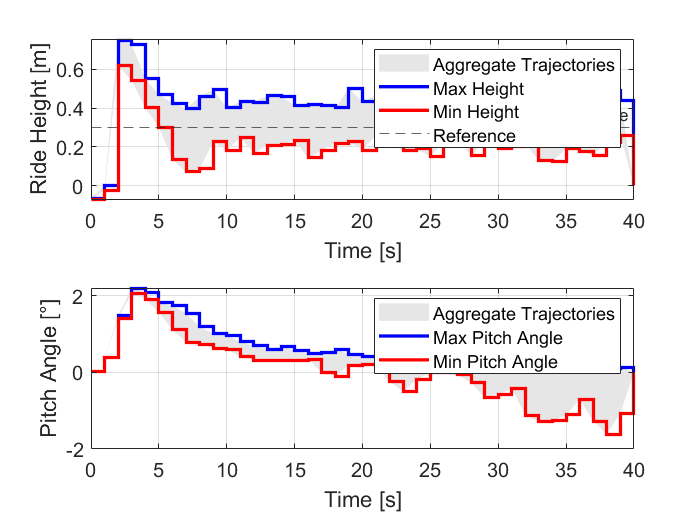

% Aggregating 'z' and 'theta' from all experiments
z_aggregate = []; 
theta_aggregate = [];

for exp = 1:N_exp
    y = all_y{exp}; 
    z_aggregate = [z_aggregate; y(1, 1:end-1)]; 
    theta_aggregate = [theta_aggregate; y(2,1:end-1)]; 
end


% Start by finding the highest and lowest trajectories for both z and theta
max_z = max(z_aggregate, [], 1); % Maximum at each time step
min_z = min(z_aggregate, [], 1); % Minimum at each time step

max_theta = max(theta_aggregate, [], 1); % Maximum at each time step
min_theta = min(theta_aggregate, [], 1); % Minimum at each time step

% Time vector for plotting
time_vector = 0:T_sim-1;

figure,

% Subplot 1 for 'Height [m]' corresponding to 'z'
subplot(2,1,1);
fill([time_vector fliplr(time_vector)], [max_z fliplr(min_z)], [0.9 0.9 0.9], 'LineStyle', 'none'); 
hold on;
stairs(time_vector, max_z, 'LineWidth', 2, 'Color', 'r'); 
stairs(time_vector, min_z, 'LineWidth', 2, 'Color', 'b'); 
yline(0.3, '--', 'Reference');
ylabel('Ride Height [m]');
xlabel('Time [s]');
grid on;
set(gca, 'FontSize', 12);

% Subplot 2 for '\theta'
subplot(2,1,2);
fill([time_vector fliplr(time_vector)], [max_theta fliplr(min_theta)], [0.9 0.9 0.9], 'LineStyle', 'none'); 
hold on;
stairs(time_vector, max_theta, 'LineWidth', 2, 'Color', 'r'); 
stairs(time_vector, min_theta, 'LineWidth', 2, 'Color', 'b'); 
ylabel('Pitch Angle [°]');
xlabel('Time [s]');
grid on;
set(gca, 'FontSize', 12);
legend('Aggregate Trajectories', 'Max', 'Min');